# Fitting of a polynomial using least-squares method

Approximating a dataset using a polynomial equation is useful when conducting engineering calculations as it allows results to be quickly updated when inputs change without the need for manual lookup of the dataset.

More theory from [Wolfram ](https://mathworld.wolfram.com/LeastSquaresFittingPolynomial.html)

NOTE: this LiveScript requires input_check.m script in order to run

% clearing command window and workspace is OPTIONAL
clc;
clear;

## 1.Parameters of approximation

- a - Polynomial coefficient

- k - The degree of the polynomial

- N - The number of points to be regressed

- e - Error

N = input('enter the # of points to be regressed: ');
k = input('enter the degree of the polynomial: ');

input_check
if wrong_input == 1
    return
end
clear wrong_input;
% see input_check.m for more details

m = k + 1;
MatrixA=zeros(m,m);

**Load points from file**

M = load('data.txt');
X = M(1,1:N);
Y = M(2,1:N);
clear M;

## 2.Creation of matrices

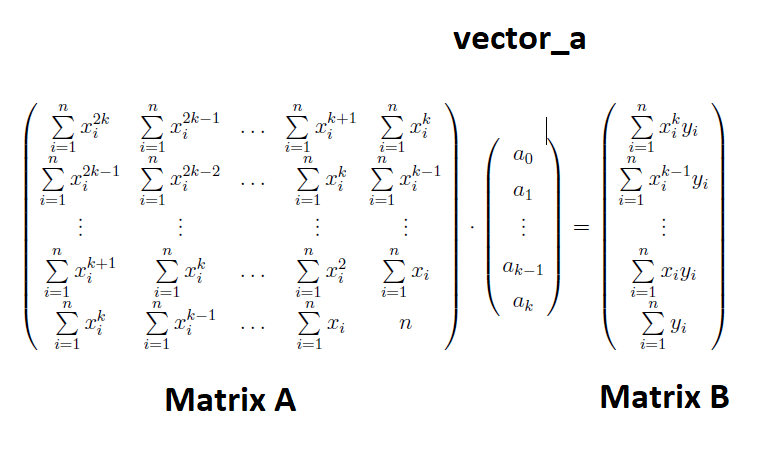

**Matrix A:**

Creation of vector in which future elements of A will be stored. Length of vector is equal to # of calculations + 1 for N.

semi_results = 1:(2*k)+1;

semi_results(1,1) = N;

Loop which calculates and fills each element into "results" vector

for pwr = 1:2*k
    semi_results(1,1+pwr)=sum(X.^pwr);
end
clear pwr;

% after fill-up, vector needs to be flipped 
semi_results=fliplr(semi_results);

Filling the matrix A with "results" array, row by row

for i = 1:m
    warning('off');
    MatrixA(i,:) = semi_results(1,i:m+j);
    j=j+1;
end 
clear i j results;

MatrixA

MatrixA =      2142595      376761       67171       12201        2275
      376761       67171       12201        2275         441
       67171       12201        2275         441          91
       12201        2275         441          91          21
        2275         441          91          21           6


**Matrix B**

Creation of another results vector which will be transposed into matrix B. Lenght is K + 1 for first element which is sum of Y.

semi_results = 1:m;

semi_results(1,1)=sum(Y);

for pwr = 1:k
    Xpow = X.^pwr;
    semi_results(1,1+pwr)=sum(Xpow.*Y);
end
clear m pwr Xpow;

semi_results = fliplr(semi_results);
MatrixB = semi_results'

MatrixB =        17836
        3340
         652
         136
          32


clear semi_results;

## 3.Result

vector_a = MatrixA\MatrixB

vector_a =     0.1667
   -2.3519
   11.2778
  -19.6323
   12.6667



Results = polyval(vector_a,X);

Sum of least-squares errors.

e = sum((Results - Y).^2)

e = 4.0635

Show polynomial and plot results.

polynomial_squares = poly2sym(vector_a)

$$polynomial\_squares = \frac{3002399751689949\,x^{4}}{18014398509481984}-\frac{82748430656395\,x^{3}}{35184372088832}+\frac{198400764841567\,x^{2}}{17592186044416}-\frac{2762997092927743\,x}{140737488355328}+\frac{55708589142689}{4398046511104}$$

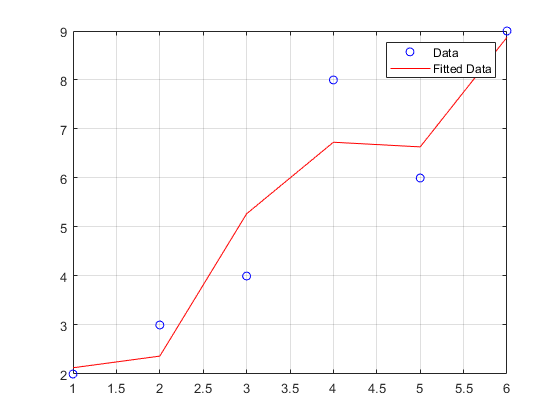


plot(X,Y, 'bo',X,Results,'-r');
grid;
legend('Data','Fitted Data');

**Verification:**

semi_results = polyfit(X,Y,k);

Results_verif = polyval(semi_results,X); 

polynomial_verif = poly2sym(semi_results)

$$polynomial\_verif = \frac{x^{4}}{6}-\frac{127\,x^{3}}{54}+\frac{203\,x^{2}}{18}-\frac{7421\,x}{378}+\frac{7130699410003471}{562949953421312}$$

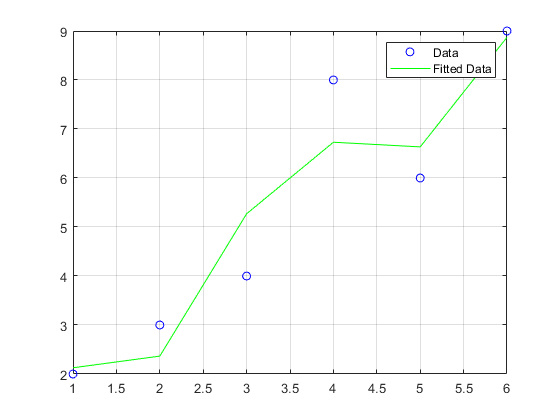


plot(X,Y, 'bo',X,Results_verif,'-g');
grid;
legend('Data','Fitted Data');


clear semi_results;

*David Polakovic, 2020*